# AMO

# PROJEKT 2

# RAWICKI PAWEŁ 

## OPIS PROJEKTU

W ramach projektu zostały zaimplementowane skrypty do wyznaczania podziałów na dwa zbiory.

Zadanie zostało wykonane przy następującej deompozycji:

- W pierwszej części, wyznaczyłem dodatkowo SVM dla płaszczyzny w 3 wymiarach. Zrobiłem to w celu, weryfikacji zaimplementowanego rozwiązania oraz, by zwizualizować problem.

- Rozwiązanie dla płaszczyzny trzy wymiarowej zostało zostało rozszerzone następnie do przestrzeni pięciowymiarowej i dla danych wdbc.

- W rozwiązaniu korzystałem z dwóch podejść, do wyznaczania rozwiązania: funkcji solve, która automatycznie wybiera odpowiedni algorytm z zestawu funkcji optymalizyjących Matlaba. Oraz funkcją fmincon dla zadania prymalnego i quadprog dla zadania dualnego

- W zadaniu prymalnym został wykorzystany twardy margines

- W zadaniu z własnym danymi, losowo je generowałem, tyle samo punktów uczących co testowych

- Dane wdbc arbitralnie podzieliłem na zbiór uczący się i testowy

- Została zbadane dwie następujące płaszczyzny, punkty wybrałem tak, by nie były zbytnio oczywiste:

% Do wielu wymiarów
% baseRatios=[10,15,20,25,30,50];

% Do trzech wymiarów.
% A=-10;
% B=10;
% C=20;
% D=30;

## WNIOSKI

Wnioski załaczam na samym początku, projektu, ponieważ niżej załącze wiele funkcji

Implementacja solvera dla funkcja solve, ma kolosalne znaczenie. Dla niezakomentowanej treści, została wykorzystana funkcja fmincon. Dla zakomentowanej, było wykorzystywany solver quadprog, czyli z programowania kwadratowego. Ponadtwo, w przypadku z pętlą, algorytm działał zdecydowanie wolniej, a dla danych rzędu 200 punktów, nie udało mi się otrzymać wyników, ponieważ dział zbyt długo. Wynika z tego, że mnożenie macierzy działa zdecydowanie szybciej w Matlabie niż iterowanie po pętli

type solveOptimizeThis.m

function [result]=solveOptimizeThis(c,points,y)    
    K = points*points';
    H = diag(y)*diag(c)*K*diag(y)*diag(c);
    result =(sum(c)-0.5*sum(sum(H)));
end

% SLOWER VERSION, SOLVER TAKES QUADPROG TO THIS
% function [result]=solveOptimizeThis(c,points,y)
%     sumIJ=0;
%     for i=1: length(points)
%       for j=1: length(points)  
%           sumIJ=sumIJ+y(i)*c(i)*points(i,:)*points(j,:)'*y(j)*c(j);
%       end
%     end
%     result =(sum(c)-0.5*sumIJ);
% end


Wykorzystanie funkcji solve jest zdecydowanie wolniejsze niż użycie quadprog lub fmincon.

Zadanie dualne jest liczone, zdecydowanie szybciej niz zadanie prymalne. Dla danych generowanych losowo, oba zadania tak samo dobrze wyznaczają zadaną płaszczyznę. Niestety dla zbioru wdbc zadanie dualne radzi sobie zdecydowanie gorzej.

## PRZEBIEG PROJEKU

### WYKORZYSTANE FUNKCJE

#### FUNKCJA DO GENEROWANIA DANYCH

type generateData.m

function [pointsAbove,pointsBelow, pointsLearn,pointsAboveTest,pointsBelowTest,pointsTest,y] = generateData(amountOfPointsAbove,amountOfPointsBelow,baseRatios)
    dimensionsAmount=length(baseRatios)-1;

    pointsAbove =zeros(amountOfPointsAbove,dimensionsAmount);
    pointsBelow=zeros(amountOfPointsBelow,dimensionsAmount);

    pointsAboveTest =zeros(amountOfPointsAbove,dimensionsAmount);
    pointsBelowTest=zeros(amountOfPointsBelow,dimensionsAmount);

    for k=1:amountOfPointsAbove
        points=rand(dimensionsAmount-1,1)*200-100;
        z=(baseRatios(1:end-2)*points+baseRatios(end))/(-baseRatios(end-1));
        z=z+rand(1)*100;
        pointsAbove(k,:)=[points',z];

        points=rand(dimensionsAmount-1,1)*200-100;
        z=(baseRatios(1:end-2)*points+baseRatios(end))/(-baseRatios(end-1));
        z=z+rand(1)*100;
        pointsAboveTest(k,:)=[points',z];
    end

    for k=1:amountOfPointsBelow
        points=rand(dimensionsAmount-1,1)*200-100;
        z=(baseRatios(1:end-2

#### FUNKCJA DO RYSOWANIA WYNIKÓW

type drawSurface.m

function  drawSurface(chartTitle,functionDuration,ratios,baseRatios,pointsAbove,pointsBelow, badlyClassified)
    amountOfPointsAbove=length(pointsAbove);
    amountOfPointsBelow=length(pointsBelow);
    amountOfPoints=amountOfPointsAbove+amountOfPointsBelow;

    [X,Y] = meshgrid(-100:5:100,-100:5:100);
    Z = (baseRatios(1)*X+baseRatios(2)*Y+baseRatios(4))/(-baseRatios(3));

    Z1=(ratios(1)*X+ratios(2)*Y+ratios(4))/(-ratios(3));
    figure
    CO(:,:,:) = ones(length(X)); % red
    CO(:,:,2) = ones(length(X)).*linspace(0.5,0.6,length(X)); % green
    CO(:,:,3) = ones(length(X)).*linspace(0,1,length(X)); % blue
    surf(X,Y,Z,CO)
    hold on
    surf(X,Y,Z1)
    hold on
    for k=1:amountOfPointsAbove
        scatter3(pointsAbove(k,1),pointsAbove(k,2),pointsAbove(k,3),'r')
    hold on
    end
    for k=1:amountOfPointsBelow
        scatter3(pointsBelow(k,1),pointsBelow(k,2),pointsBelow(k,3),'b')
    hold on
    end
    title(chartTitle +newline +...
        "WSPÓŁCZYNNIKI PŁASZCZYZ

#### FUNKJCA DO SPRAWDZANIA WYNIKÓW

type validateResults.m

function [countBadlyClassifiedLearnData,countBadlyClassifiedTestData] = validateResults(pointsLearn,yLearn,pointsTest,yTest,ratios)
    countBadlyClassifiedLearnData=0;
    countBadlyClassifiedTestData=0;
    for k=1:length(pointsLearn)
      resultLearn=  [pointsLearn(k, :),1]*ratios';
      if(resultLearn*yLearn(k)<=0)
           countBadlyClassifiedLearnData=countBadlyClassifiedLearnData+1;
      end

    end
    for k=1:length(pointsTest)
      resultTest=  [pointsTest(k, :),1]*ratios';
      if(resultTest*yTest(k) <=0)
        countBadlyClassifiedTestData=countBadlyClassifiedTestData+1;
      end
    end
end



#### FUNKCJA DO WYLICZANIA QUADPROG W ZADANIU DUALNYM

type dualQuadprog.m

function [ ratios, functionDuration ] = dualQuadprog( points, y )
    C = 1;
    N = length(y);
    K = points*points';
    H = 2*diag(y)*K*diag(y);
    f = -ones(N,1);
    Aeq = y';
    beq = [0];
    LB = zeros(N,1);
    UB = C*ones(N,1);
    
    tic
    ratios = quadprog(H, f, [], [], Aeq, beq, LB, UB, []);
    functionDuration=toc;
end


#### FUNKCJA DO WYLICZANIA SOLVE W ZADANIU DUALNYM

type dualSolve.m

function [cRatios,functionDuration] = dualSolve(points,y)   
    amountOfPoints=length(points);

    flow = optimvar('c',amountOfPoints);
    
    obj=solveOptimizeThis(flow,points,y);
    p = optimproblem('Objective', obj,'ObjectiveSense','maximize');

    p.Constraints.constr1=optimconstr(amountOfPoints);
    p.Constraints.constr2=optimconstr(amountOfPoints);

    for k=1:amountOfPoints
        p.Constraints.constr1(k)=flow(k)>=0;
        p.Constraints.constr2(k)=flow(k)<=1/(2*amountOfPoints);
    end
    p.Constraints.equality=y'*flow==0;

    x0.c=zeros(amountOfPoints,1);
    
    tic
    sol= solve(p,x0);
    functionDuration =toc;
    cRatios=sol.c;
    
end



#### FUNKCJA DO WYLICZANIA FMICON W ZADANIU PRYMALNYM

type primalFmincon.m

function [ratios,functionDuration] = primalFmincon(pointsAbove,pointsBelow,planeDimension)
    amountOfPointsAbove=length(pointsAbove);
    amountOfPointsBelow=length(pointsBelow);
    amountOfPoints=amountOfPointsAbove+amountOfPointsBelow;

    A=zeros(amountOfPoints,planeDimension+1);
    b=zeros(amountOfPoints,1);
    for k=1:amountOfPointsAbove
        A(k,:)=[pointsAbove(k,:),1];
        b(k)=-1;
    end
    for k=1:(amountOfPointsBelow)   
        A(k+amountOfPointsAbove,:)=-[pointsBelow(k,:),1];
        b(k+amountOfPointsAbove)=-1;
    end

    % HARD MARGIN
    fun= @(x)sqrt(sum(x(1:end-1).^2));

    x0=zeros(1,planeDimension+1);
    tic
    % I DO NOT KNOW WHY BUT FOR VALIDATION SIGN MATTERS
    ratios = -fmincon(fun,x0,A,b);
    functionDuration=toc;
end



#### FUNKCJA DO WYLICZANIA SOLVE W ZADANIU PRYMALNYM

type primalSolve.m

function [ratios,functionDuration] = primalSolve(pointsAbove,pointsBelow,planeDimension)
    amountOfPointsAbove=length(pointsAbove);
    amountOfPointsBelow=length(pointsBelow);
    
    flow = optimvar('W',planeDimension+1);

    % HARD MARGIN
    fun= @(x)sqrt(sum(x(1:end-1).^2));

    obj =fun(flow);

    problem = optimproblem('Objective', obj,'ObjectiveSense','minimize');

    problem.Constraints=optimconstr(amountOfPointsAbove+amountOfPointsBelow);
    for k=1:amountOfPointsAbove
        problem.Constraints(k) = (pointsAbove(k,:)*flow(1:end-1)+flow(end))>=1;
    end
    for k=1:amountOfPointsBelow
        problem.Constraints(k+amountOfPointsAbove) = -(pointsBelow(k,:)*flow(1:end-1)+flow(end))>=1;
    end

    x0.W=ones(1,planeDimension+1);

    tic;
    sol= solve(problem,x0);
    functionDuration=toc;

    ratios=sol.W';
end


#### FUNKCJA DO WYLICZANIA WSPÓŁCZYNNIKÓW W ZADANIU DUALNYM

type getDualRatios.m

function [ratios] = getDualRatios(pointsAbove,pointsBelow,cRatios)
    amountOfPointsAbove=length(pointsAbove);
    amountOfPointsBelow=length(pointsBelow);
    
    adding=cRatios(1:amountOfPointsAbove);
    substracting =cRatios(amountOfPointsAbove+1:end);

    W=adding'*pointsAbove-substracting'*pointsBelow;
    
    bUp=zeros(amountOfPointsAbove,1);
    for k=1: amountOfPointsAbove
        bUp(k)=-(W*pointsAbove(k,:)')+1; 
    end
    
    bDown=zeros(amountOfPointsBelow,1);
    for k=1: amountOfPointsBelow
        bDown(k)=-(W*pointsBelow(k,:)')-1;   
    end

    b=(min(bUp)+max(bDown))/2;
    ratios=[W,b];
end



### PŁASZCZYZNA W 3D

#### ZADANIE PRYMALNE

type myPrimal3D.m

clear all;

% DECLARE PLANE
%  Ax+By+Cz+D=0
A=-10;
B=10;
C=20;
D=30;
baseRatios=[A,B,C,D];
planeDimension=length(baseRatios)-1;

amountOfPointsAbove =100;
amountOfPointsBelow =100;

%  GENERATE DATA
[pointsAbove,pointsBelow, pointsLearn,pointsAboveTest,pointsBelowTest,pointsTest,y] = generateData(amountOfPointsAbove,amountOfPointsBelow,baseRatios);

% FIND PLANE FACTORS
[ratiosFmincon,functionDurationFmincon] = primalFmincon(pointsAbove,pointsBelow,planeDimension);
clearAllMemoizedCaches; % CLEARING CACHES, BECAUSE SOLVE USES CACHE FROM FMINCON
[ratiosSolve,functionDurationSolve] = primalSolve(pointsAbove,pointsBelow,planeDimension);

% COUNT WRONGLY CLASSIFIED DATA
[countBadlyClassifiedLearnDataFmincon,countBadlyClassifiedTestDataFmincon] = validateResults(pointsLearn,y,pointsTest,y,ratiosFmincon);
[countBadlyClassifiedLearnDataSolve,countBadlyClassifiedTestDataSolve] = validateResults(pointsLearn,y,pointsTest,y,ratiosSolve);

% DRAW DATA
chartTitle="ZADANIE PRYMALNE, DANE UCZĄCE" +ne


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization co

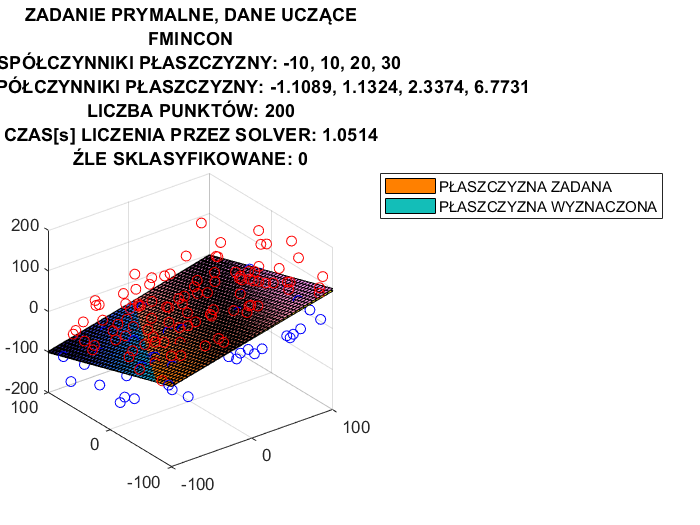

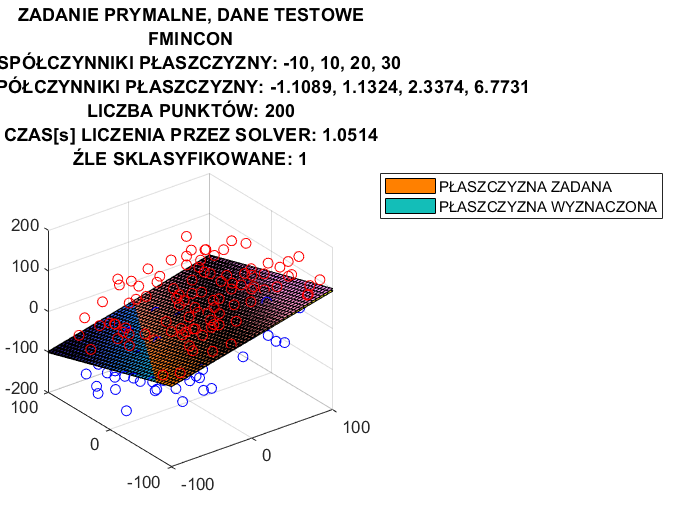

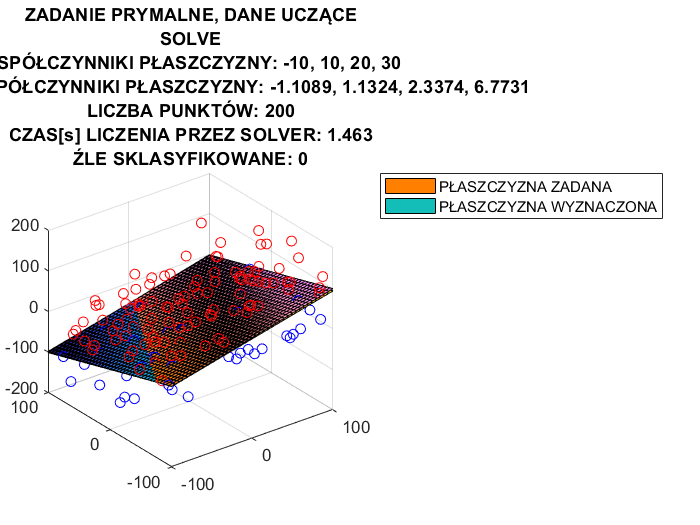

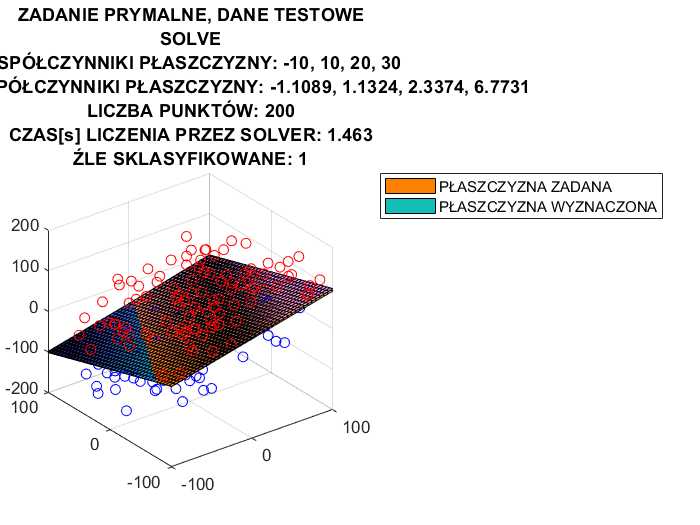

myPrimal3D;

#### ZADANIE DUALNE

type myDual3D.m

clear all;

% DECLARE PLANE
A=-10;
B=10;
C=20;
D=30;

baseRatios=[A,B,C,D];

amountOfPointsAbove =100;
amountOfPointsBelow =100;

amountOfPoints=amountOfPointsAbove+amountOfPointsBelow;

% GENERATE DATA
[pointsAbove,pointsBelow, pointsLearn,pointsAboveTest,pointsBelowTest,pointsTest,y] = generateData(amountOfPointsAbove,amountOfPointsBelow,baseRatios);

% FIND PLANE FACTORS WITHOUT b
[cRatiosSolve,functionDurationSolve] = dualSolve(pointsLearn,y);
clearAllMemoizedCaches; % CLEARING CACHES, BECAUSE SOLVE USES CACHE FROM FMINCON
[cRatiosQuadprog, functionDurationQuadprog]=dualQuadprog(pointsLearn,y);

% ADD b TO PLANE FACTORS
ratiosQuadprog=getDualRatios(pointsAbove,pointsBelow,cRatiosQuadprog);
ratiosSolve=getDualRatios(pointsAbove,pointsBelow,cRatiosSolve);

% COUNT WRONGLY CLASSIFIED DATA
[countBadlyClassifiedLearnDataQuadprog,countBadlyClassifiedTestDataQuadprog] = validateResults(pointsLearn,y,pointsTest,y,ratiosQuadprog);
[countBadlyClassifiedLearnDataSolve,countBadlyClassifiedTest

Solving problem using quadprog.
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



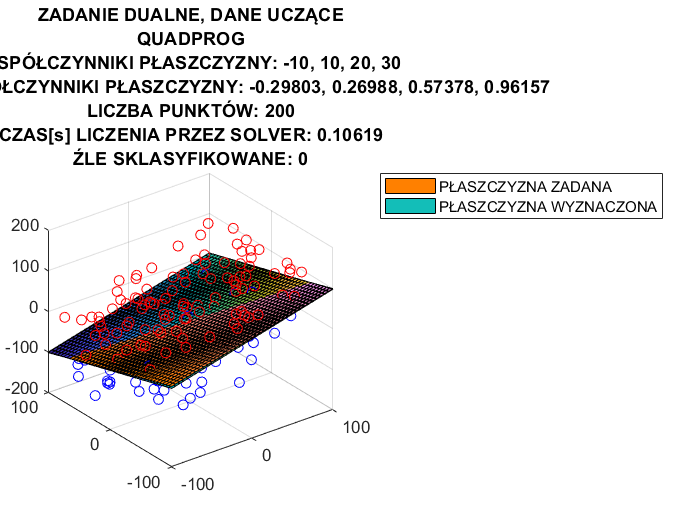

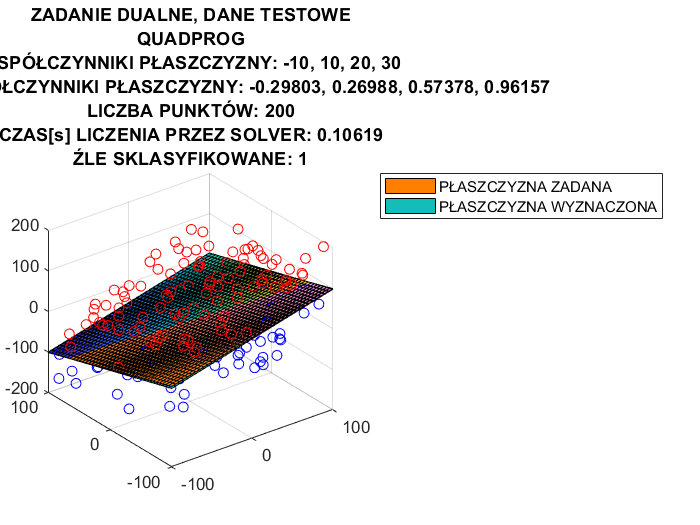

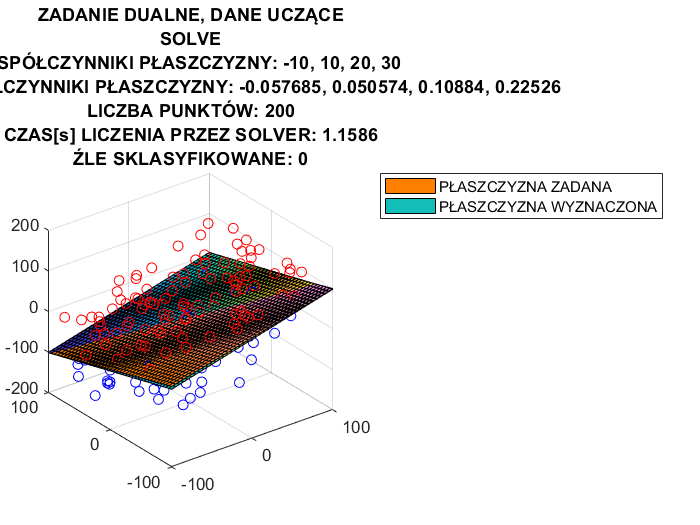

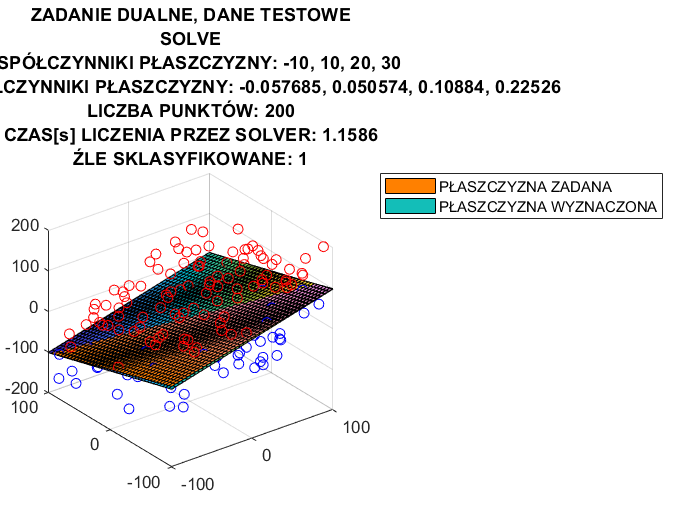

myDual3D;

### PRZESTRZEŃ PIĘCIO WYMIAROWA

#### ZADANIE PRYMALNE

type myPrimal.m

clear all;

% DECLARE PLANE
baseRatios=[10,15,20,25,30,50];
planeDimension=length(baseRatios)-1;

amountOfPointsAbove =100;
amountOfPointsBelow =100;
amountOfPoints=amountOfPointsAbove+amountOfPointsBelow;

% GENERATE DATA
[pointsAbove,pointsBelow, pointsLearn,pointsAboveTest,pointsBelowTest,pointsTest,y] = generateData(amountOfPointsAbove,amountOfPointsBelow,baseRatios);

% FIND PLANE FACTORS
[ratiosFmincon,functionDurationFmincon] = primalFmincon(pointsAbove,pointsBelow,planeDimension);
clearAllMemoizedCaches; % CLEARING CACHES, BECAUSE SOLVE USES CACHE FROM FMINCON
[ratiosSolve,functionDurationSolve] = primalSolve(pointsAbove,pointsBelow,planeDimension);


% COUNT WRONGLY CLASSIFIED DATA
[countBadlyClassifiedLearnDataFmincon,countBadlyClassifiedTestDataFmincon] = validateResults(pointsLearn,y,pointsTest,y,ratiosFmincon);
[countBadlyClassifiedLearnDataSolve,countBadlyClassifiedTestDataSolve] = validateResults(pointsLearn,y,pointsTest,y,ratiosSolve);

% DISPLAY RESULTS
disp("ZADANIE P

myPrimal;


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization co

#### ZADANIE DUALNE

type myDual.m

clear all;

% DECLARE PLANE
baseRatios=[10,15,20,25,30,50];
planeDimension=length(baseRatios)-1;

amountOfPointsAbove =100;
amountOfPointsBelow =100;
amountOfPoints=amountOfPointsAbove+amountOfPointsBelow;

% GENERATE DATA
[pointsAbove,pointsBelow, pointsLearn,pointsAboveTest,pointsBelowTest,pointsTest,y] = generateData(amountOfPointsAbove,amountOfPointsBelow,baseRatios);

% FIND PLANE FACTORS WITHOUT b
[cRatiosSolve,functionDurationSolve] = dualSolve(pointsLearn,y);
clearAllMemoizedCaches; % CLEARING CACHES, BECAUSE SOLVE USES CACHE FROM FMINCON
[cRatiosQuadprog, functionDurationQuadprog]=dualQuadprog(pointsLearn,y);

% ADD b TO PLANE FACTORS
ratiosQuadprog=getDualRatios(pointsAbove,pointsBelow,cRatiosQuadprog);
ratiosSolve=getDualRatios(pointsAbove,pointsBelow,cRatiosSolve);

% COUNT WRONGLY CLASSIFIED DATA
[countBadlyClassifiedLearnDataQuadprog,countBadlyClassifiedTestDataQuadprog] = validateResults(pointsLearn,y,pointsTest,y,ratiosQuadprog);
[countBadlyClassifiedLearnDataSolve,coun

myDual;

Solving problem using quadprog.
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



### DANE WBDC

#### ZADANIE PRYMALNE

type wdbcPrimal.m

clear all;

planeDimension=30;

% READ DATA
dataLearn=readtable('wdbcLearn.dat');
pointsAboveLearn=table2array(dataLearn(strcmpi(dataLearn.Var31,{'B'})>0,1:planeDimension));
pointsBelowLearn=table2array(dataLearn(strcmpi(dataLearn.Var31,{'M'})>0,1:planeDimension));
pointsLearn=[pointsAboveLearn;pointsBelowLearn];
amountPointsAboveLearn=length(pointsAboveLearn);
amountPointsBelowLearn=length(pointsBelowLearn);
amountOfPointsLearn=amountPointsAboveLearn+amountPointsBelowLearn;
yLearn=[ones(amountPointsAboveLearn,1);-ones(amountPointsBelowLearn,1)];

dataTest=readtable('wdbcTest.dat');
pointsAboveTest=table2array(dataTest(strcmpi(dataTest.Var31,{'B'})>0,1:planeDimension));
pointsBelowTest=table2array(dataTest(strcmpi(dataTest.Var31,{'M'})>0,1:planeDimension));
pointsTest=[pointsAboveTest;pointsBelowTest];
amountPointsAboveTest=length(pointsAboveTest);
amountPointsBelowTest=length(pointsBelowTest);
amountOfPointsTest=amountPointsAboveTest+amountPointsBelowTest;
yTest=[ones(amountPointsAbov

wdbcPrimal;


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.

ZADANIE PRYMALNE, WDBC, FMINCON
CZAS: 0.93183
LICZBA PUNKTÓW UCZĄCYCH: 350
LICZBA PUNKTÓW TESTOWYCH: 219
WYZNACZONA PŁASZCZYZNA: 85.93955, -0.5857919, -5.560106, -0.4862278, -393.7781, 167.4099, 161.8143, -249.7381, 222.8711, -42.14158, -8.19543, -3.675687, -1.676332, -0.4598528, 20.71368, 260.2816, -54.79953, -103.4178, -109.4618, 58.0289, -19.22107, -1.300

#### ZADANIE DUALNE

type wdbcDual.m

clear all;

planeDimension=30;

% READ DATA
dataLearn=readtable('wdbcLearn.dat');
pointsAboveLearn=table2array(dataLearn(strcmpi(dataLearn.Var31,{'B'})>0,1:planeDimension));
pointsBelowLearn=table2array(dataLearn(strcmpi(dataLearn.Var31,{'M'})>0,1:planeDimension));
pointsLearn=[pointsAboveLearn;pointsBelowLearn];
amountPointsAboveLearn=length(pointsAboveLearn);
amountPointsBelowLearn=length(pointsBelowLearn);
amountOfPointsLearn=amountPointsAboveLearn+amountPointsBelowLearn;
yLearn=[ones(amountPointsAboveLearn,1);-ones(amountPointsBelowLearn,1)];

dataTest=readtable('wdbcTest.dat');
pointsAboveTest=table2array(dataTest(strcmpi(dataTest.Var31,{'B'})>0,1:planeDimension));
pointsBelowTest=table2array(dataTest(strcmpi(dataTest.Var31,{'M'})>0,1:planeDimension));
pointsTest=[pointsAboveTest;pointsBelowTest];
amountPointsAboveTest=length(pointsAboveTest);
amountPointsBelowTest=length(pointsBelowTest);
amountOfPointsTest=amountPointsAboveTest+amountPointsBelowTest;
yTest=[ones(amountPointsAbov

wdbcDual;


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Solving problem using quadprog.
The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

